atom = Alkali("Lithium7");
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 1, ...
    waist = 110e-6 ...
    );
ol = OpticalLattice(atom,laser);
kL = laser.AngularWavenumber;
lambda = laser.Wavelength;
a = lambda / 2;
Er = ol.RecoilEnergy;
ol.DepthKd = 8.8458 * Er;

nq = 800;
na = 4;
qmin = - kL;
qmax =  kL;
qList = linspace(qmin,qmax,nq);
xRange = na*a;
nx = na * 5000;
xList = linspace(-xRange / 2,xRange / 2,nx);

maxband = 5;
ol.computeAll1D(qList,maxband,xList)

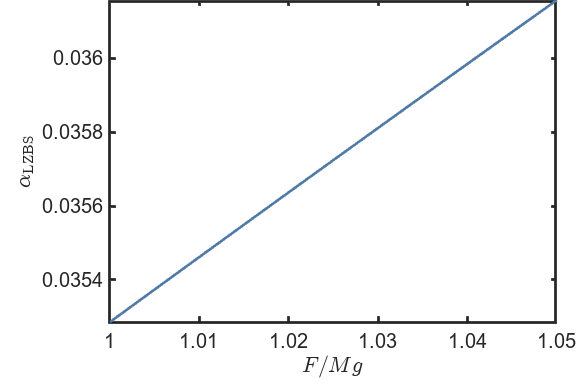

M = atom.mass;
g = 9.81;
hbar = Constants.SI("hbar");
h = hbar * 2 * pi;
F0 = M * g;
NF = 1000;
FList = linspace(1,1.05,NF) * F0;
omegaBList = FList * a / hbar;
qR = 0.80 * kL;
V0 = h * ol.DepthKd;
A = ol.ModCouplingList;
Apd = squeeze(A(2,3,:));
[~,qRIdx] = min(abs(qList-qR));
[~,qRIdx2] = min(abs(qList+qR));
E = h * ol.BandEnergyList;
Ed = E(3,:);
Ep = E(2,:);
dq = qList(2) - qList(1);
dEdq = gradient(Ed-Ep,dq);
alphaList = 1 / (V0) / abs(Apd(qRIdx)) .*...
    sqrt(log(4)/pi.*FList.*abs(dEdq(qRIdx)));

tList = (FList ./ hbar^2 * abs(dEdq(qRIdx))).^(-1/2);

vList = FList ./ hbar^2 * abs(dEdq(qRIdx));
alpha = 0.035;
Omega = alpha * V0 * abs(Apd(qRIdx)) / hbar;
deltaList = Omega^2 / 4 ./ vList;
PList = exp(-2*pi*deltaList);

gammaarg = sym(1-1i*deltaList);
gammaList = double(gamma(gammaarg));
phiS = pi/4 + deltaList .* (log(deltaList) - 1) + angle(gammaList);

dE = Ed - Ep;
dE = dE - dE(qRIdx);
phiD = sum(dE(qRIdx:end)) + sum(dE(1:qRIdx2));
phiD = phiD * dq ./ FList;

pop = 4*PList .* (1-PList) .* (sin(phiD/2 + phiS)).^2;

close(figure(1))
fig = figure(1);
plot(FList / F0,alphaList);
xlabel("$F / Mg$",'Interpreter','latex')
ylabel("$\alpha_{\mathrm{LZBS}}$",'Interpreter','latex')
axis([-inf,inf,-inf,inf])
render
savePDF(fig,'alpha')

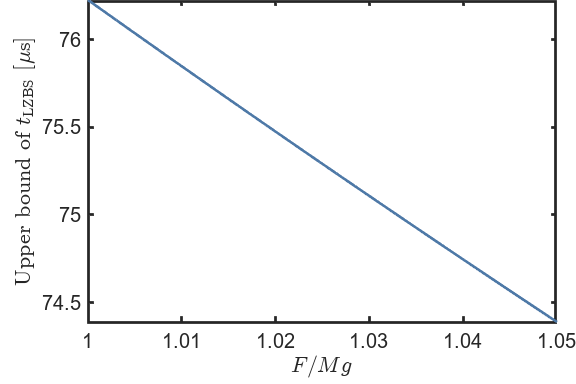


close(figure(1))
fig = figure(1);
plot(FList / F0,tList * 1e6);
xlabel("$F / Mg$",'Interpreter','latex')
ylabel("Upper bound of $t_{\mathrm{LZBS}}~[\mu \mathrm{s}]$",'Interpreter','latex')
axis([-inf,inf,-inf,inf])
render
savePDF(fig,'t')

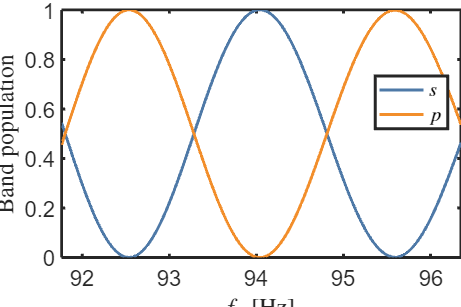


close(figure(1))
fig = figure(1);
plot(omegaBList / 2 / pi,1 - pop,omegaBList / 2 / pi,pop);
xlabel("$f_{\mathrm{B}}$ [Hz]",'Interpreter','latex')
ylabel("Band population",'Interpreter','latex')
axis([-inf,inf,0,1])
legend("$s$","$p$",'Interpreter','latex')
render
savePDF(fig,'pop')

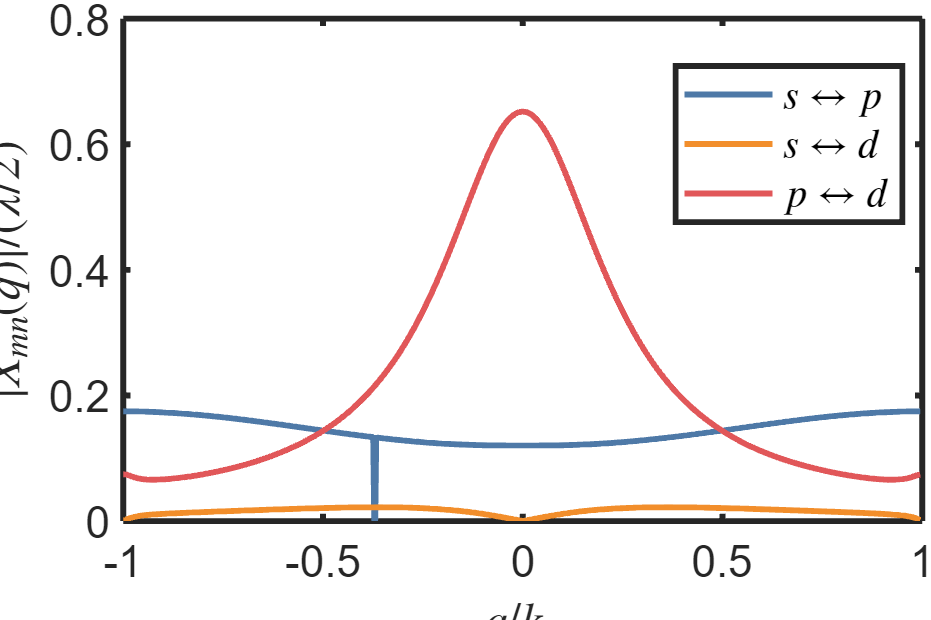

X = ol.BoCouplingList;
close(figure(1))
fig = figure(1);
idx = [1:267,270:798];
plot(qList(idx)/kL,abs(squeeze(X(1,2,idx))) ./ a , qList(idx)/kL,abs(squeeze(X(1,3,idx))) ./ a , qList(idx)/kL,abs(squeeze(X(2,3,idx))) ./ a);
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|X_{mn}(q)| / (\lambda / 2)$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render
savePDF(fig,'X')

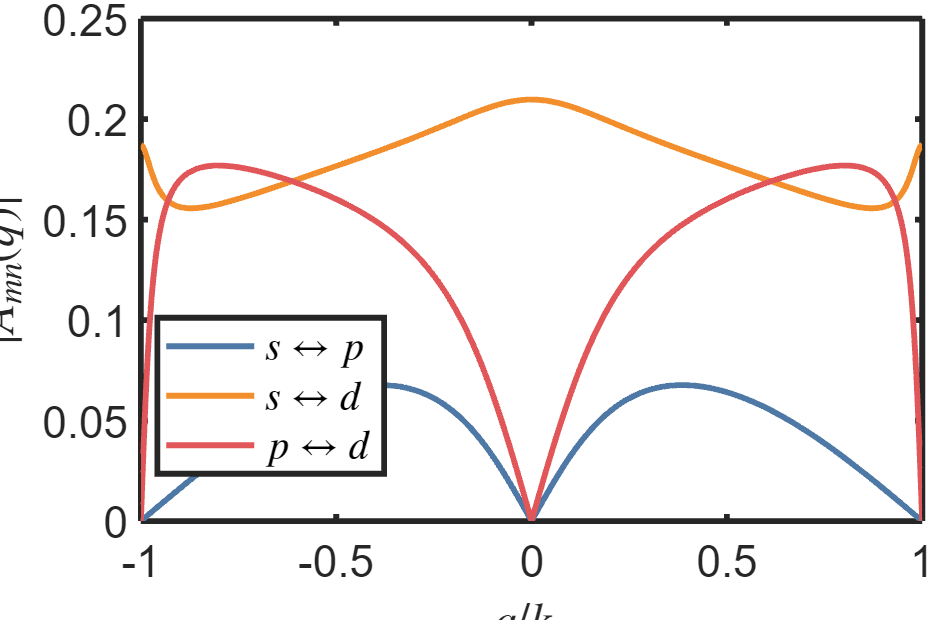

A = ol.ModCouplingList;
close(figure(1))
fig = figure(1);
ax = gca;
plot(ax,qList/kL,abs(squeeze(A(1,2,:))),qList/kL,abs(squeeze(A(1,3,:))),qList/kL,abs(squeeze(A(2,3,:))));
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|A_{mn}(q)|$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render
savePDF(fig,'A')

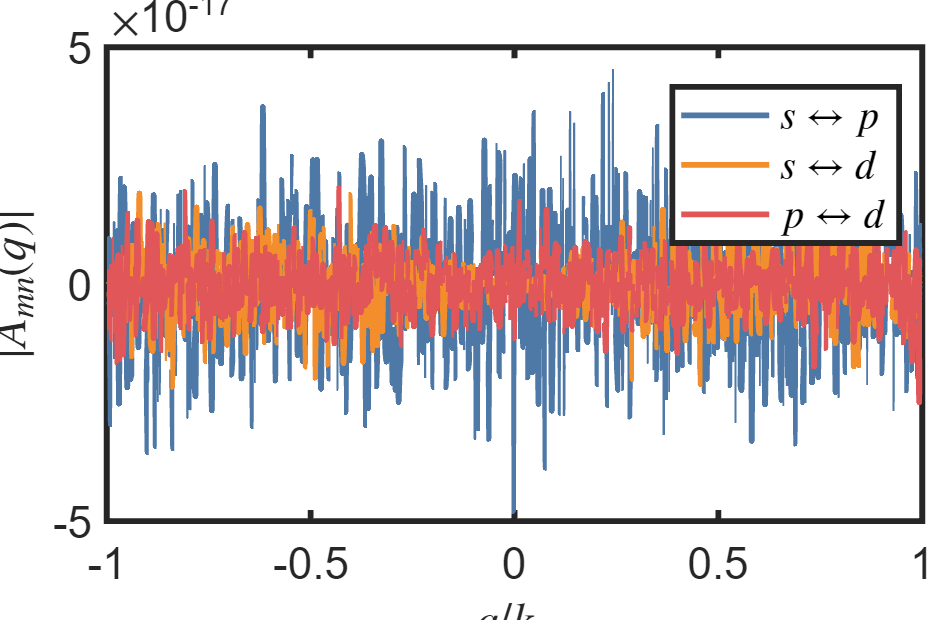

A = ol.ModCouplingList;
close(figure(1))
fig = figure(1);
ax = gca;
plot(ax,qList/kL,imag(squeeze(A(1,2,:))),qList/kL,imag(squeeze(A(1,3,:))),qList/kL,imag(squeeze(A(2,3,:))));
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|A_{mn}(q)|$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render
savePDF(fig,'A_angle')